clear all
cd("C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Previous work\Bachelor-main\Bachelor-main\Simulation_Bachelor_Project\Matlab")
load("linearizeModelOldAndNew.mat")
load("stepDataUnlinear.mat")
load("pitchStep15.mat")%pitchData, pitchTime

linsysNew

linsysNew =
 
  A = 
                 Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim
   Drone_2M_sim             0             0             0             0             0             1             0             0             0
   Drone_2M_sim             0             0             0             0             0             0             0             1             0
   Drone_2M_sim             0             0     4.651e-12    -3.856e-09     3.161e-07             0             0             0           0.5
   Drone_2M_sim             0             0    -4.806e-08    -4.473e-09    -3.687e-06             0             0             0    -0.0002184
   Drone_2M_sim             0             0    -3.177e-07     3.688e-06     2.099e-11             0             0             0      0.007039
   Drone_2M_sim        -179.3        -28.92         20.27        -39.46       -0.2145        -35.85     5.936e-13        -5.783

linsysOld

linsysOld =
 
  A = 
                 Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim
   Drone_2M_sim             0             0             0             0             0             1             0             0             0
   Drone_2M_sim             0             0             0             0             0             0             0             1             0
   Drone_2M_sim             0             0     2.744e-11    -5.606e-08     8.293e-07             0             0             0           0.5
   Drone_2M_sim             0             0     5.608e-08     1.083e-12    -3.694e-06             0             0             0     0.0002132
   Drone_2M_sim             0             0    -8.277e-07     3.694e-06     2.391e-11             0             0             0    -6.542e-07
   Drone_2M_sim        -179.5         39.88         20.25           -36        0.2873         -35.9     8.017e-12         7.976

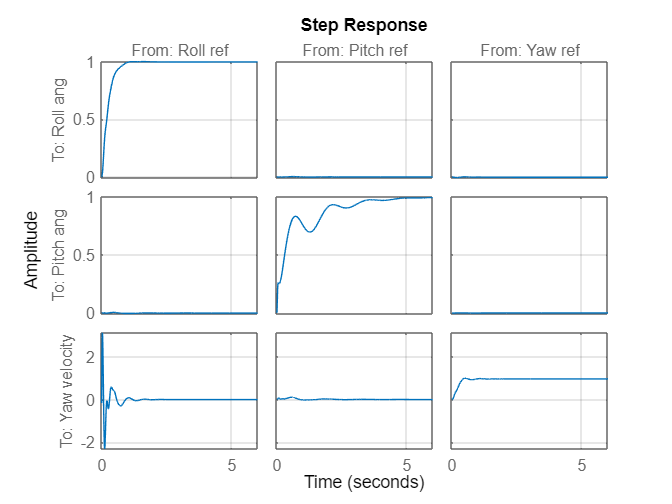

step(linsysNew)
grid on

tol=1.5e-2

tol = 0.0150

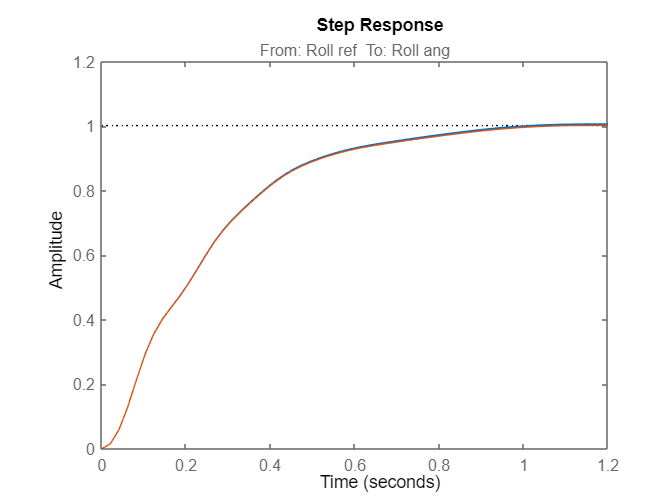

H=tf(linsysNew);
%step
clf
step(minreal(H(1,1),tol)) %roll
hold on
step(H(1,1)) %roll
hold off

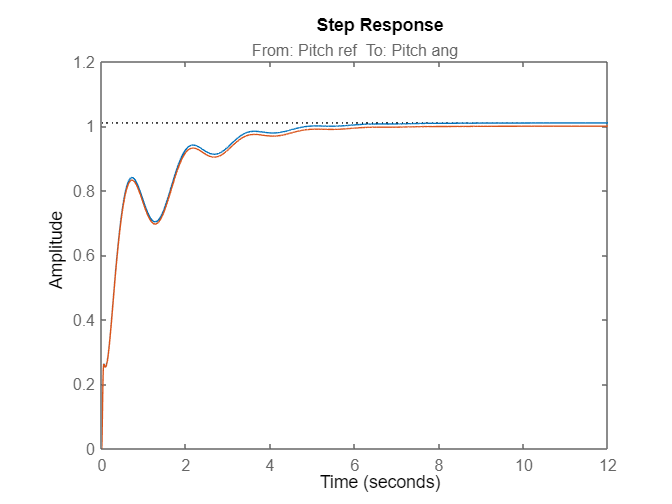

step(minreal(H(2,2),tol)) %pitch
hold on
step(H(2,2)) %roll
hold off

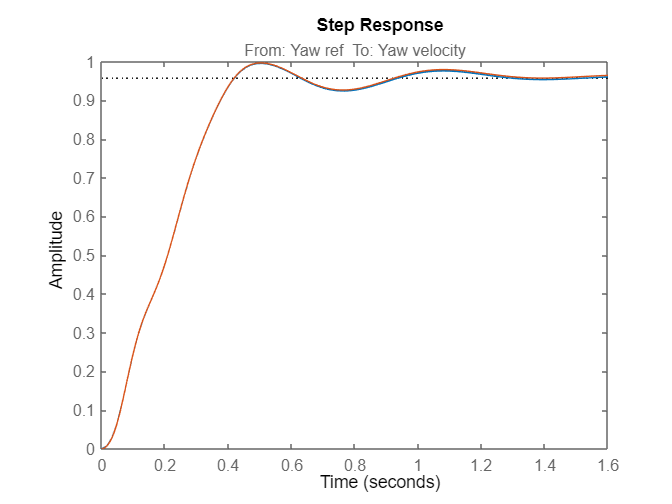

step(minreal(H(3,3),tol)) %yaw
hold on
step(H(3,3)) %roll
hold off

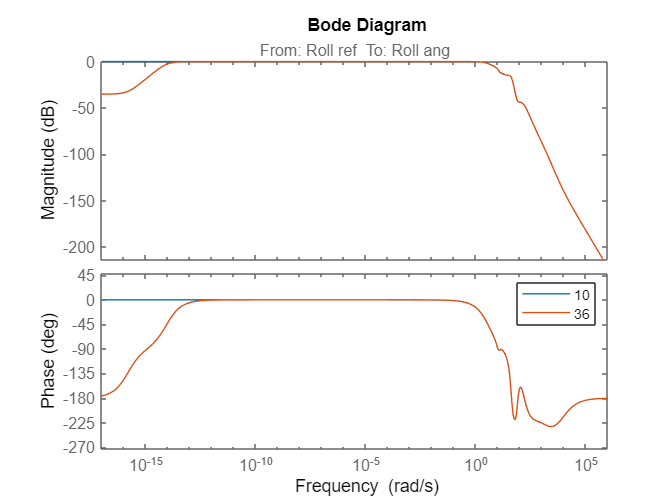

%bode
bode(minreal(H(1,1),tol)) %roll
hold on
bode(H(1,1)) %roll
legend("10","36")
hold off

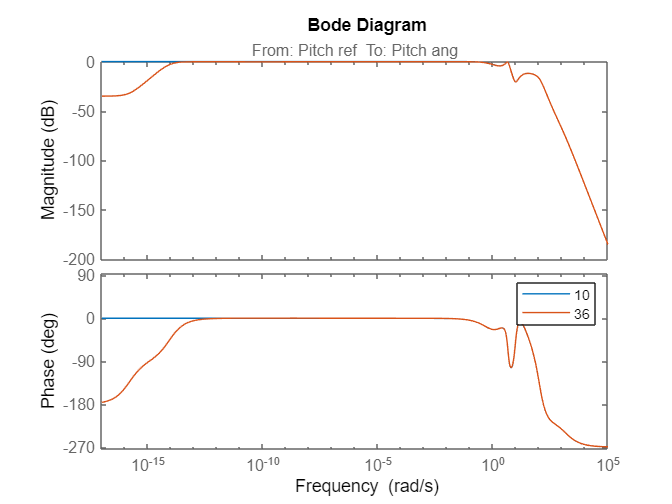

bode(minreal(H(2,2),tol)) %pitch
hold on
bode(H(2,2)) %roll
legend("10","36")
hold off

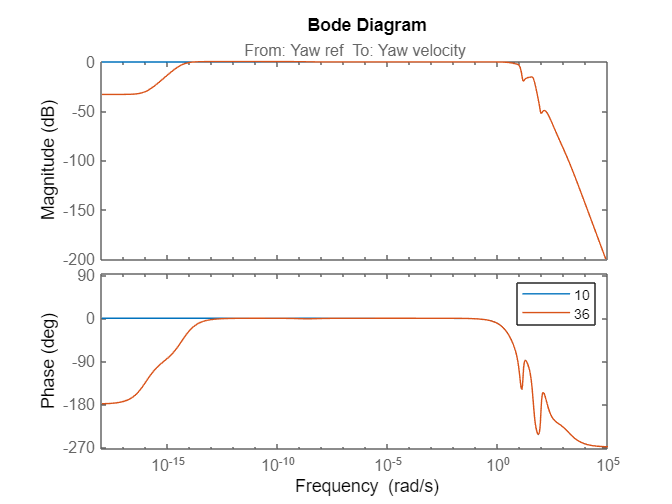

bode(minreal(H(3,3),tol)) %yaw
hold on
bode(H(3,3)) %roll
legend("10","36")
hold off

H_New=tf(linsysNew)

H_New =
 
  From input "Roll ref" to output...
                                                                                                                                     
              7.514 s^33 + 7.48e04 s^32 + 1.249e08 s^31 + 7.05e10 s^30 + 1.819e13 s^29 + 3.026e15 s^28 + 3.513e17 s^27               
                                                                                                                                     
                      + 3.014e19 s^26 + 1.955e21 s^25 + 9.495e22 s^24 + 3.438e24 s^23 + 9.41e25 s^22 + 1.989e27 s^21 + 3.311e28 s^20 
                                                                                                                                     
                      + 4.404e29 s^19 + 4.722e30 s^18 + 4.09e31 s^17 + 2.858e32 s^16 + 1.603e33 s^15 + 7.188e33 s^14 + 2.547e34 s^13 
                                                                                                                                     
               

H_Old=tf(linsysOld)

H_Old =
 
  From input "Roll ref" to output...
                                                                                                                                      
              -19.81 s^33 + 3.673e04 s^32 + 1.18e08 s^31 + 7.292e10 s^30 + 1.936e13 s^29 + 3.238e15 s^28 + 3.707e17 s^27              
                                                                                                                                      
                      + 3.113e19 s^26 + 1.959e21 s^25 + 9.206e22 s^24 + 3.252e24 s^23 + 8.783e25 s^22 + 1.852e27 s^21 + 3.103e28 s^20 
                                                                                                                                      
                      + 4.188e29 s^19 + 4.591e30 s^18 + 4.096e31 s^17 + 2.969e32 s^16 + 1.738e33 s^15 + 8.156e33 s^14 + 3.021e34 s^13 
                                                                                                                                      
        

%bode old vs new
%{
%roll
bode(minreal(H_New(1,1),tol))
hold on
bode(minreal(H_Old(1,1),tol))
legend("Old","New")
hold off
%}
%pitch
clf
display("NEW")

    "NEW"



bode(minreal(H_New(2,2),tol))
grid on
hold on
yticks([-90, -80, -60, -40, -20, -3, 0])
display("OLD")

    "OLD"



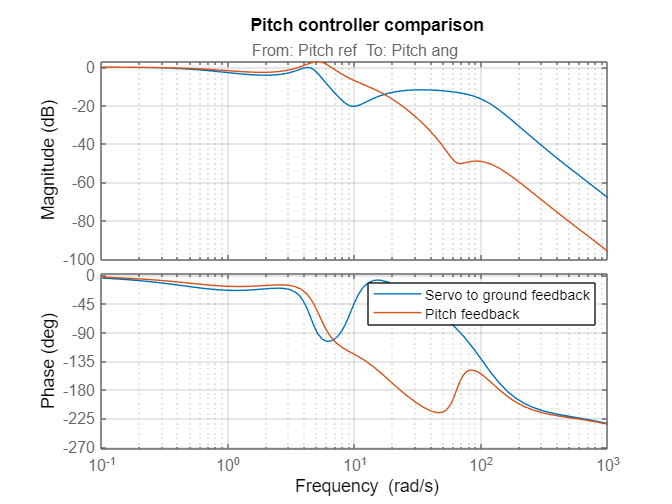

bode(minreal(H_Old(2,2),tol))
grid on
plot([1,1],[0,0.001])
hold off
legend("Servo to ground feedback","Pitch feedback")
xlim([1e-1 1e3])
title("Pitch controller comparison")

%title("Old pitch controller")

bandwith_ServoToGround=bandwidth(minreal(H_New(2,2),tol))

bandwith_ServoToGround = 1.0081

bandwidth_pitch=bandwidth(minreal(H_Old(2,2),tol))

bandwidth_pitch = 7.6038


calculatedRisetime_STG=0.35/bandwith_ServoToGround

calculatedRisetime_STG = 0.3472

calculatedRisetime_P=0.35/bandwidth_pitch

calculatedRisetime_P = 0.0460

%{
%yaw
bode(minreal(H_New(3,3),tol))
hold on
bode(minreal(H_Old(3,3),tol))
legend("Old","New")
hold off
%}

%step comparasin old ctr

clf %roll
%plot(t,RollStep20(1:length(t)));
t

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


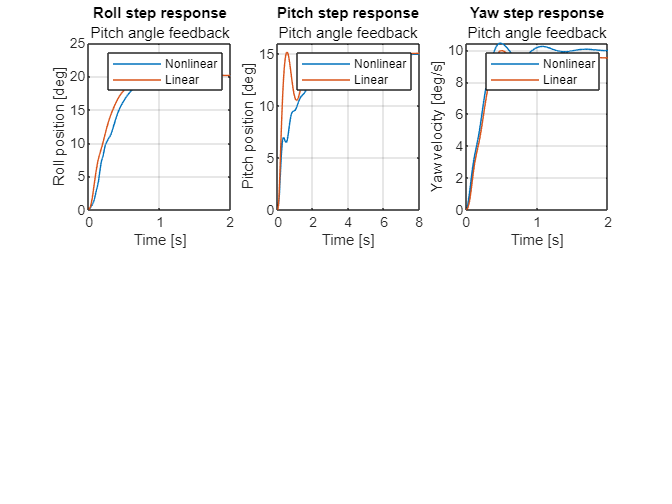

subplot(2,3,1)
rollStepfilt=RollStep20(t>=5)*(-1);
[y,tOut]=step(minreal(H_Old(1,1)*20,tol),4);
plot(t(1:length(rollStepfilt)),rollStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Roll step response","Pitch angle feedback")
xlim([0 2])
xlabel('Time [s]');
ylabel('Roll position [deg]')
grid on

%fit = compare()

%pitch
subplot(2,3,2)
[y,tOut]=step(minreal(H_Old(2,2)*15,tol),8) ;
pitchStepfilt=pitchData(pitchTime>=13)*(-1);
plot(pitchTime(1:length(pitchStepfilt)),pitchStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Pitch step response","Pitch angle feedback")
xlim([0 8]),ylim([0 16])
xlabel('Time [s]');
ylabel('Pitch position [deg]')
grid on

%yaw
subplot(2,3,3)
%plot(t(1:length(yawStep10)),yawStep10);
[y,tOut]=step(minreal(H_Old(3,3)*10,tol),2) ;
grid on
yawStepfilt=yawStep10(t(1:length(yawStep10))>=5)*(-1);
plot(t(1:length(yawStepfilt)),yawStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Yaw step response","Pitch angle feedback")
xlim([0 2])
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
grid on

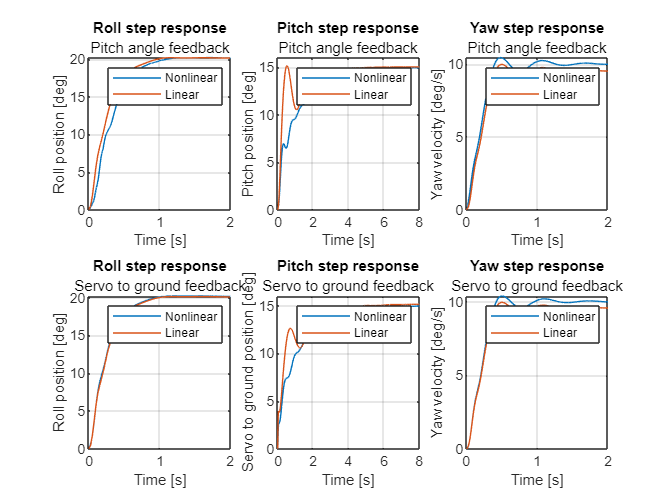

% step comparasion new ctr
load("stepNewCtr.mat")%output, time
 %roll
subplot(2,3,4)
%plot(t,RollStep20(1:length(t)));
RollStep20=output(:,1);
rollStepfilt=RollStep20(time>=5)*(-2);
[y,tOut]=step(minreal(H_New(1,1)*20,tol),4);
plot(time(1:length(rollStepfilt)),rollStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Roll step response","Servo to ground feedback")
xlim([0 2])
xlabel('Time [s]');
ylabel('Roll position [deg]')
grid on

%pitch
subplot(2,3,5)
pitchData=output(:,2);
[y,tOut]=step(minreal(H_New(2,2)*15,tol),8);
pitchStepfilt=pitchData(time>=13)*(-1);
plot(time(1:length(pitchStepfilt)),pitchStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Pitch step response","Servo to ground feedback")
xlim([0 8]),ylim([0 16])
xlabel('Time [s]');
ylabel('Servo to ground position [deg]')
grid on

%yaw
subplot(2,3,6)
%plot(t(1:length(yawStep10)),yawStep10);
yawStep10=output(:,3);
[y,tOut]=step(minreal(H_New(3,3)*10,tol),2);
grid on
yawStepfilt=yawStep10(time(1:length(yawStep10))>=33)*(-1);
plot(time(1:length(yawStepfilt)),yawStepfilt)
hold on
plot(tOut,y)
hold off
legend("Nonlinear","Linear")
title("Yaw step response","Servo to ground feedback")
xlim([0 2])
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
grid on

pitch_New=minreal(H_New(2,2),tol)%12 ordens

pitch_New =
 
  From input "Pitch ref" to output "Pitch ang":
                                                                                                                                   
  5.513e05 s^9 + 2.389e08 s^8 + 7.753e09 s^7 + 1.608e11 s^6 + 2.22e12 s^5 + 2.258e13 s^4 + 1.64e14 s^3 + 8.463e14 s^2 + 2.681e15 s 
                                                                                                                                   
                                                                                                                       + 2.989e15  
                                                                                                                                   
  ---------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                  
   s^12 + 1337 

pitch_Old=minreal(H_Old(2,2),tol)%11 ordens

pitch_Old =
 
  From input "Pitch ref" to output "Pitch ang":
                                                                                                                                
  2.218e04 s^8 + 1.101e07 s^7 + 1.012e09 s^6 + 7.125e10 s^5 + 3.181e12 s^4 + 5.659e13 s^3 + 4.676e14 s^2 + 1.709e15 s + 1.951e15
                                                                                                                                
  -------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                 
  s^11 + 1382 s^10 + 3.23e05 s^9 + 4.104e07 s^8 + 2.746e09 s^7 + 9.869e10 s^6 + 2.032e12 s^5 + 2.536e13 s^4 + 1.874e14 s^3       
                                                                                                                                 
                               


pitchNew_zero=sort(zero(pitch_New))

pitchNew_zero = 1.0e+02 *

  -0.0200 + 0.0000i
  -0.0667 + 0.0000i
  -0.0231 - 0.0914i
  -0.0231 + 0.0914i
  -0.0726 - 0.0700i
  -0.0726 + 0.0700i
  -0.0279 - 0.1023i
  -0.0279 + 0.1023i
  -4.0000 + 0.0000i


pitchNew_pole=sort(pole(pitch_New))

pitchNew_pole = 1.0e+03 *

  -0.0008 + 0.0000i
  -0.0009 - 0.0044i
  -0.0009 + 0.0044i
  -0.0027 - 0.0103i
  -0.0027 + 0.0103i
  -0.0121 + 0.0000i
  -0.0100 - 0.0103i
  -0.0100 + 0.0103i
  -0.0530 + 0.0000i
  -0.0593 - 0.0892i



pitchOld_zero=sort(zero(pitch_Old))

pitchOld_zero = 1.0e+02 *

  -0.0200 + 0.0000i
  -0.0667 + 0.0000i
  -0.0834 - 0.0390i
  -0.0834 + 0.0390i
  -0.4809 + 0.0000i
  -0.1133 - 0.6258i
  -0.1133 + 0.6258i
  -4.0000 + 0.0000i


pitchOld_pole=sort(pole(pitch_Old))

pitchOld_pole = 1.0e+03 *

  -0.0009 + 0.0000i
  -0.0014 - 0.0051i
  -0.0014 + 0.0051i
  -0.0138 + 0.0000i
  -0.0108 - 0.0115i
  -0.0108 + 0.0115i
  -0.0309 + 0.0000i
  -0.0488 + 0.0000i
  -0.0688 - 0.0891i
  -0.0688 + 0.0891i




rlocus(pitch_New,0:0.1:17.78)
grid on
title("NEW")
yLimed=170

yLimed = 170

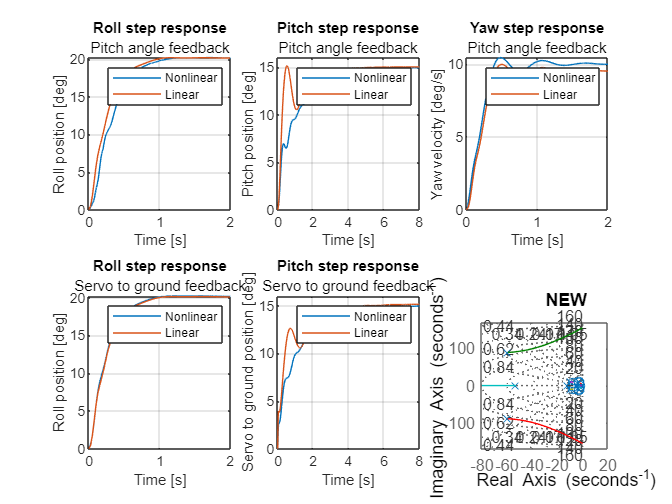

xlim([-80 20])
ylim([-yLimed yLimed])

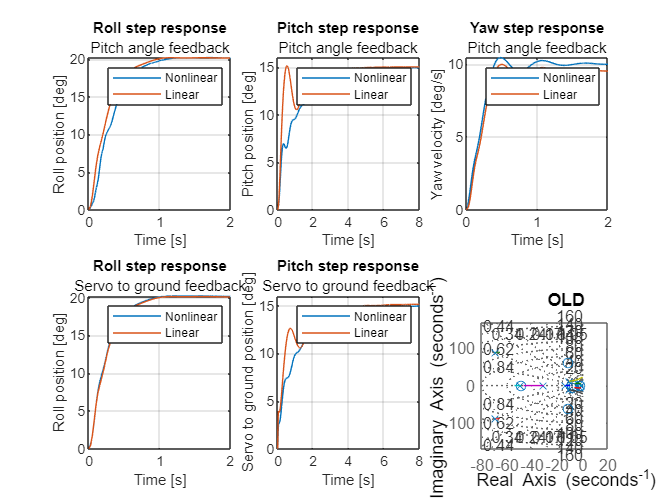


rlocus(pitch_Old,0:0.1:9.2)
xlim([-80 20])
ylim([-yLimed yLimed])
title("OLD")
grid on

%forståelses test
syms x s
vpasolve(19.3==20*log10(x))

$$ans = 9.2257142715476316003073802267767$$

vpasolve(25==20*log10(x))

$$ans = 17.782794100389228012254211951927$$

%s=tf('s')
real=3,img=-10

real = 3

img = -10

H_test=1/((s+real+img*i)*(s+real-img*i))

$$H\_test = \frac{1}{\left(s+3-10\,\mathrm{i}\right)\,\left(s+3+10\,\mathrm{i}\right)}$$

factor(simplify(H_test))

$$ans = \frac{1}{s^{2}+6\,s+109}$$

zpk

ans =

  Empty zero-pole-gain model.



%{
pole(H_test)
step(H_test)
clf
subplot(1,1,1)
bode(H_test)
10^0
%}

## Nyquist

syms G_cl G_ol
G_cl==G_ol/(1+G_ol)

$$ans = G_{\mathrm{cl}}=\frac{G_{\mathrm{ol}}}{G_{\mathrm{ol}}+1}$$

G_ol=solve(ans,G_ol)

$$G\_ol = -\frac{G_{\mathrm{cl}}}{G_{\mathrm{cl}}-1}$$

pitch_New_ol=minreal(-pitch_New/(pitch_New-1))

pitch_New_ol =
 
  From input "Pitch ang" to output "Pitch ang":
                                                                                                                                   
  5.513e05 s^9 + 2.389e08 s^8 + 7.753e09 s^7 + 1.608e11 s^6 + 2.22e12 s^5 + 2.258e13 s^4 + 1.64e14 s^3 + 8.463e14 s^2 + 2.681e15 s 
                                                                                                                                   
                                                                                                                       + 2.989e15  
                                                                                                                                   
  ---------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                  
   s^12 + 13

pitch_Old_ol=minreal(-pitch_Old/(pitch_Old-1))

pitch_Old_ol =
 
  From input "Pitch ang" to output "Pitch ang":
                                                                                                                                
  2.218e04 s^8 + 1.101e07 s^7 + 1.012e09 s^6 + 7.125e10 s^5 + 3.181e12 s^4 + 5.659e13 s^3 + 4.676e14 s^2 + 1.709e15 s + 1.951e15
                                                                                                                                
  -------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                 
  s^11 + 1382 s^10 + 3.23e05 s^9 + 4.102e07 s^8 + 2.735e09 s^7 + 9.768e10 s^6 + 1.961e12 s^5 + 2.218e13 s^4 + 1.308e14 s^3       
                                                                                                                                 
                            



pole_new_ol=pole(pitch_New_ol)

pole_new_ol = 1.0e+03 *

  -1.1253 + 0.0000i
  -0.0705 + 0.0895i
  -0.0705 - 0.0895i
  -0.0197 + 0.0005i
  -0.0197 - 0.0005i
  -0.0123 + 0.0110i
  -0.0123 - 0.0110i
  -0.0027 + 0.0103i
  -0.0027 - 0.0103i
  -0.0008 + 0.0035i


zero_new_ol=zero(pitch_New_ol)

zero_new_ol = 1.0e+02 *

  -4.0000 + 0.0000i
  -0.0279 + 0.1023i
  -0.0279 - 0.1023i
  -0.0231 + 0.0914i
  -0.0231 - 0.0914i
  -0.0726 + 0.0700i
  -0.0726 - 0.0700i
  -0.0667 + 0.0000i
  -0.0200 + 0.0000i


pole_old_ol=pole(pitch_Old_ol)

pole_old_ol = 1.0e+03 *

  -1.1254 + 0.0000i
  -0.0692 + 0.0890i
  -0.0692 - 0.0890i
  -0.0487 + 0.0000i
  -0.0205 + 0.0007i
  -0.0205 - 0.0007i
  -0.0134 + 0.0095i
  -0.0134 - 0.0095i
  -0.0008 + 0.0034i
  -0.0008 - 0.0034i


zero_old_ol=zero(pitch_Old_ol)

zero_old_ol = 1.0e+02 *

  -4.0000 + 0.0000i
  -0.1133 + 0.6258i
  -0.1133 - 0.6258i
  -0.4809 + 0.0000i
  -0.0834 + 0.0390i
  -0.0834 - 0.0390i
  -0.0667 + 0.0000i
  -0.0200 + 0.0000i



pitch_New_ol_fac=zpk(pitch_New_ol)

pitch_New_ol_fac =
 
  From input "Pitch ang" to output "Pitch ang":
                                                                                                                         
                   5.5135e05 (s+400) (s+6.667) (s+2) (s^2 + 14.53s + 101.8) (s^2 + 4.611s + 88.91) (s^2 + 5.584s + 112.4)
                                                                                                                         
  -----------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                           
  (s+1125) (s-0.01325) (s^2 + 39.3s + 386.4) (s^2 + 1.606s + 13.01) (s^2 + 5.432s + 112.5) (s^2 + 24.53s + 270.6) (s^2 + 141.1s + 1.298e04)
                                                                                                                                           
     

pitch_Old_ol_fac=zpk(pitch_Old_ol)

pitch_Old_ol_fac =
 
  From input "Pitch ang" to output "Pitch ang":
                       22184 (s+400) (s+48.09) (s+6.667) (s+2) (s^2 + 16.68s + 84.78) (s^2 + 22.67s + 4045)
  ------------------------------------------------------------------------------------------------------------------------------
  (s+1125) (s+48.74) (s-0.003306) (s^2 + 41.08s + 422.4) (s^2 + 1.619s + 12.42) (s^2 + 26.72s + 269.6) (s^2 + 138.3s + 1.271e04)
 
Continuous-time zero/pole/gain model.



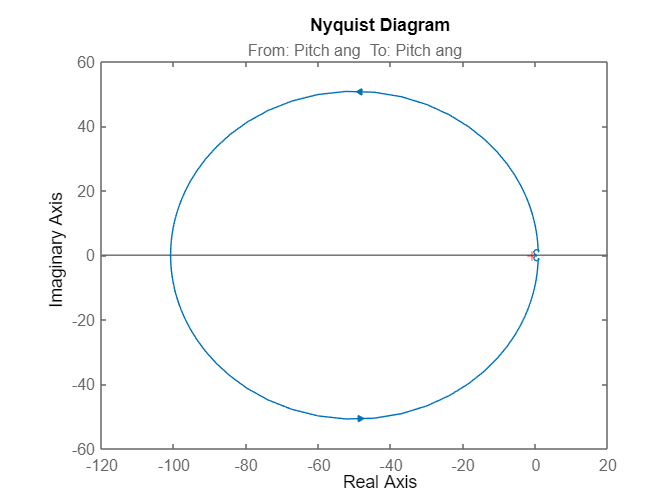


clf
nyquist(pitch_New_ol)

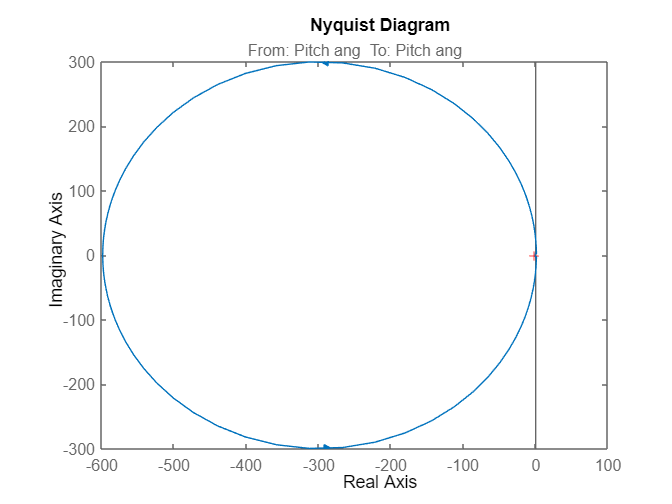

nyquist(pitch_Old_ol)

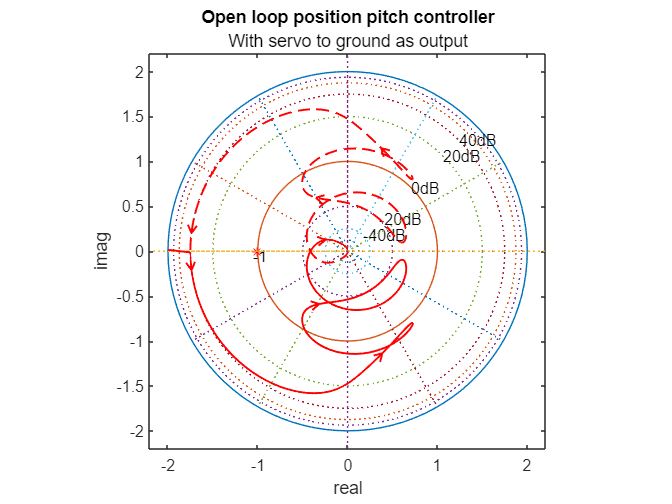

Closed_Logarithmic_Nyquist(pitch_New_ol)
grid off
title("Open loop position pitch controller","With servo to ground as output")

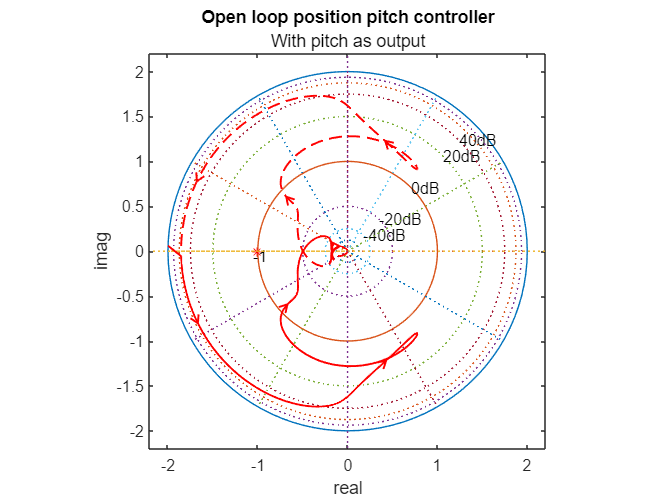

Closed_Logarithmic_Nyquist(pitch_Old_ol)
title("Open loop position pitch controller", "With pitch as output")
grid off



%aflæst på matlabs non  log graf:
GM_OLD_min=1/600

GM_OLD_min = 0.0017

GM_OLD_max=1/0.096

GM_OLD_max = 10.4167

GM_New_min=1/100

GM_New_min = 0.0100

GM_New_max=1/0.053

GM_New_max = 18.8679


%aflæst på polar plot:
PM_old=abs(angle(0.729-0.682i)/pi*180)

PM_old = 43.0922

PM_new=abs(angle(0.472+0.883i)/pi*180)

PM_new = 61.8737

syms x
20*log10(0.0531)%new

ans = -25.4981

20*log10(0.0952)%old

ans = -20.4273


zeros = 0;
poles = [1-1i 1+1i 2];
gain = -2;
sys = zpk(zeros,poles,gain)

sys =
 
          -2 s
  --------------------
  (s-2) (s^2 - 2s + 2)
 
Continuous-time zero/pole/gain model.

